# Domaći zadatak iz predmeta Obrada i prepoznavanje govora

# Danica Bandović 2018/0018 

## Prvi zadatak

#### 1.Korišćenjem komercijalnog mikrofona u programskom okruženju MATLAB, snimiti govornu sekvencu u dužini od 20-ak sekundi. Sekvencu snimiti sa frekvencijom odabiranja 8 ili 10 kHz, u kojoj se nalazi desetak jasno segmentiranih reči.

Kod pomoću kog je snimljena tražena sekvenca nalazi se u ćelijama ispod. Snimljena sekvenca sačuvana je i nalazi se u okviru fajla sekvenca.wav. Za frekvenciju odabiranja odabrano je 8 kHz, snimljano je 20 sekundi i izgovoreno je 10 reči.

% inicijalizacija parametara za snimanje sekvence
clear
close all
clc
fs = 8000;
T = 1/fs;
trajanje = 20; %8 sekundi za prvi pod 3
N = trajanje*fs;
nbits = 16;
nchans = 1;

% snimanje sekvence

%x = audiorecorder(fs,nbits,nchans);
%disp('Start.')

Start.


%recordblocking(x, trajanje);
%disp('Stop.')

Stop.


%pustanje snimljene sekvence

%play(x)
%y = getaudiodata(x);
%sound(y, fs); %podraz. fs = 8192
%potrebno je da vrednosti y budu u intervalu (-1,1)


%audiowrite('sekvenca.wav', y, fs);


#### 2. Korišćenjem kratkovremenske energije i kratkovremenske brzine prolaska kroz nulu izvršiti određivanje početka i kraja pojedinih reči. Dobijeni rezultat prikazati grafički. Preslušati segmentirane delove zvučne sekvence i komentarisati dobijeni rezultat. (Po želji se ovaj postupak može ponoviti primenom Teager energije).

### ***TEORIJSKI OSVRT:***

Pošto se značajne promene u govornom signalu ne dešavaju tako brzo često se u obradi govora u vremenskom domenu koriste kratkovremenske karakteristike signala. One podrazumevaju da se obrada signala vrši na odbircima koji su smešteni u okviru jednog kratkog vremenskog intervala. Ukupna energija signala ne nosi informaciju o pojavi zvučniih i bezvučnih delova signala ($E = \sum_{m=-\infty}^{\infty} x^{2}(m)$). Za razliku od nje, kratkovremenska energija se definiše kao 


$$E_{n} = \sum_{m=n-N+1}^{n}x^{2}(m)$$


gde se energija ra;una kao zbir kvadrata N poslednjih odbiraka iz intervala (n-N+1) do n. Izraz se može napisati i kao 


$$E_{n} = \sum_{m=-\infty}^{\infty}[x(m)w(n-m)]^{2}$$


gde je w(n) neka prozorska funkcija. Prethodni izraz može se zapisati i na sledeći način:


$$E_{n} = \sum_{m=-\infty}^{\infty}x^{2}(m)h(n-m), h(n) = w^{2}(n)$$


Ideja je da se kratkovremenska energija može dobiti kao izlaz iz filtra čiji je ulaz $x^{2}(n)$ a impulsni odyiv filtra h(n), i to niskofrekvencijskog jer je pretpostavka da se E ne menja brzo. Najčešći oblici prozoskih funkcija koji se koriste su pravougaona i Hamingova prozorska funkcija. Dužina prozorske funkcije iznosi 1 do 3 pitch periode.

O sadržaju snimljene sekvence može nam dosta toga reći i kratkovremenska brzina prolaska kroz nulu. To je mera frekventnog sadržaja signala. Ako u signalu ima dosta visokih učestanosti ova veličina će biti velika. Brzina prolaska kroz nulu je $Z=\frac{N_{0}}{N}$, gde je N broj posmatranih odbiraka a $N_{0}$ broj odbiraka koji nisu istog znaka kao njihovi prethodnici. Pošto govorni signal sadrži frekvemcijske komponente iz širokog spektra učestanosti, Z nije baš precizno, i zato koristimo kratkovremenski oblik :


$$Z_{n} = \sum_{m=-\infty}^{\infty}[sgn[x(m)]-sgn[x(m-1)]]x(n-m)$$



$$w(n) = \frac{1}{2N}, 0\leq n \leq N-1, inace \quad w(n)=0
        $$


Z će biti manje za govorni signal nego za bezvučni govor i šum.

Pri segmentaciji govornog dela signala, nakon računanja kratkovremenske energije i kratkovremenske brzine prolaska kroz nulu, potrebno je na osnovu energije naći dovoljno veliki prag ITU koji nam služi da ako je energija veća od ovog praga sigurno znamo da u tom intervalu imamo govorni signal. Drugi korak je određivanje praga ITL, koji služi kao donji prag, da bismo odredili početak i kraj govornog dela signala. Od onog trenutka kada je energija veća od ITU, idemo levo i desno u vremenu sve dok ne pronađemo trenutke kada je energija manja od donjeg praga, i to su potencijalni početak i kraj reči. Potom se posmatra brzina prolaska kroz nulu 25 prozorskih funkcija levo od početka i desno od kraja reči. Ako je Z 3 ili više puta presekla određeni prag, uzima se nova tačka za početak, odnosno kraj reči.

### ***REZULTATI:***

Prvo što ćemo uraditi jeste da grafički prikažemo snimljenu sekvencu, odnosno prikazaćemo odbirke snimljenog zvučnog signala u vremenu.

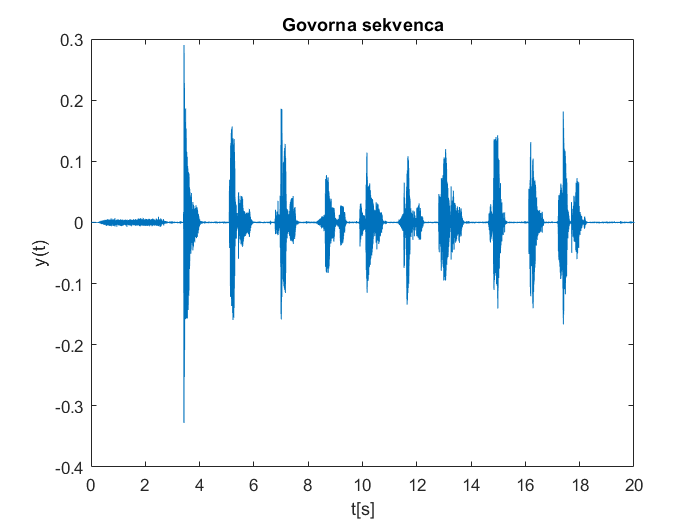

%prikaz snimljene sekvence u vremenskom domenu
[y,fs] = audioread('sekvenca.wav');

figure
plot(0:1/fs:(length(y)-1)/fs, y);
title('Govorna sekvenca'); xlabel('t[s]'); ylabel('y(t)');

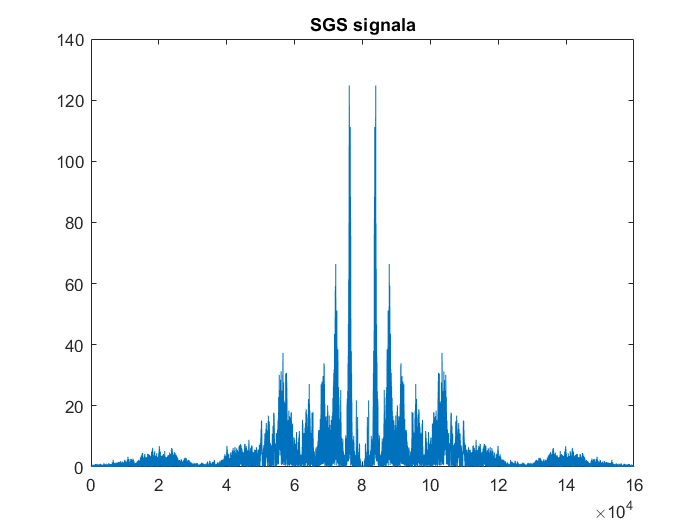


figure
plot(abs(fftshift(fft(y))))
title("SGS signala")

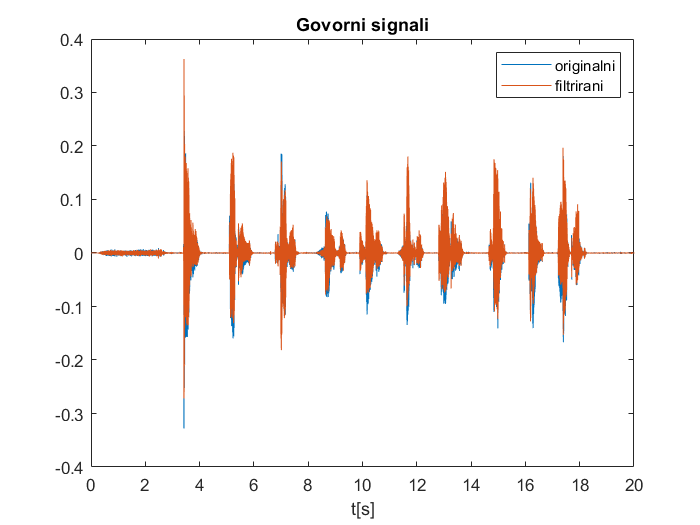

nord = 6;
Wn = [60 3400]/(fs/2);
[b,a] = butter(nord, Wn, 'bandpass');
yf = filter(b,a,y);

figure()
plot(0:1/fs:(length(y)-1)/fs,y);
hold on;
plot(0:1/fs:(length(y)-1)/fs, yf);
title('Govorni signali'); xlabel('t[s]'); legend('originalni', 'filtrirani');

y = yf;

Na grafiku se primećuje 10 izdvojenih segmenata. Na početku sekvence se primećuje određeni šum koji je ili posledica mikrofona ili nekih spoljašnjih zvukova, i s obzirom da u prve dve, tri sekunde nije izgovorena nijedna reč, možemo čak i posmatrati deo sekvence tek od treće sekunde. Ono što će biti pokušano u daljem radu jeste da se pomoću kratkovremenske energije i kratkovremenskog ZCR-a izdvoje svih pojedinačnih 10 izgovorenih reči.

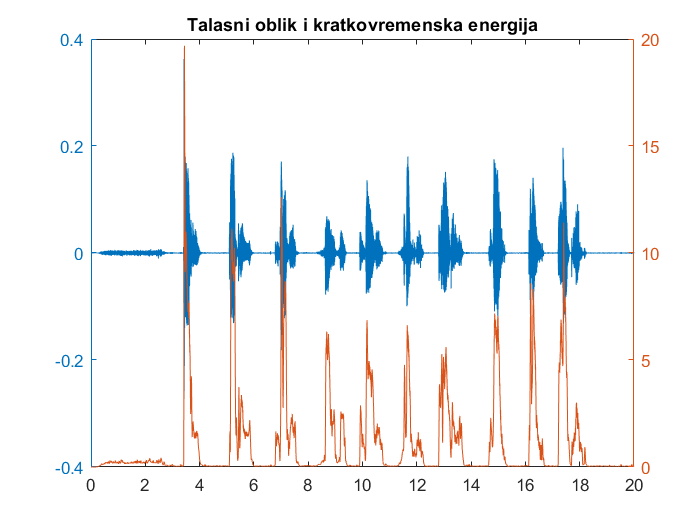

%prozor od 20ms, pravougaona prozorska fja

%pojedine reci
%y = y(136000:end);
T = 1/fs;
wl = fs*20e-3;
E = zeros(size(y));
Z = zeros(size(y));
M = zeros(size(y));
for i= wl : length(y)
    rng = (i-wl+1):i-1;
    E(i) = sum(y(rng).^2);
    M(i) = sum(abs(y(rng)));
    Z(i) = sum(abs(sign(y(rng+1)) - sign(y(rng))));
end
Z = (Z/2)/wl;
time = T:T:length(E)*T;
figure
plotyy(time, y, time, M);
title('Talasni oblik i kratkovremenska energija');

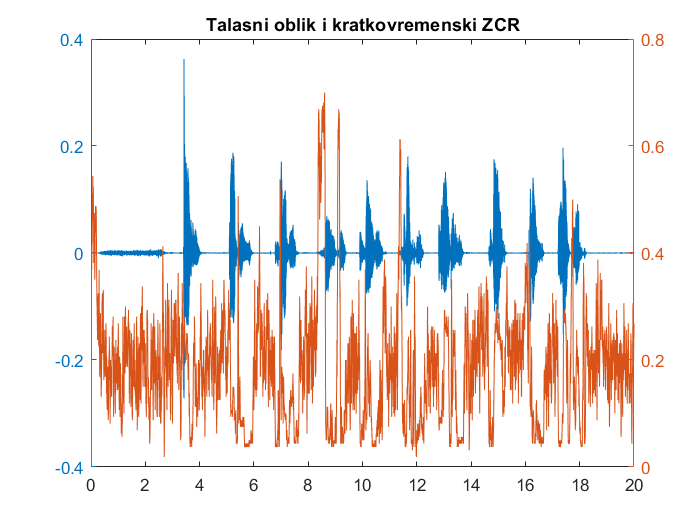

figure
plotyy(time, y, time, Z);
title('Talasni oblik i kratkovremenski ZCR');

Ono što se primećuje sa grafika energije jeste da je prisutan jedan pik čija je vrednost dosta veća u odnosu na ostatak izgovorenih reči. Zbog tog pika ćemo posebno obratiti pažnju na to koju vrednost uzimamo kao gornji prag pri segmentaciji da se ne desi da druge reči čija je energija manja, ne budu prepoznate kao reč. Reči koje imaju dosta samoglasnika i koje su zvučne se veoma lako segmentiraju, poput Ana, dva, tri, dok reči kao što su podrum, drvo, Matlab, nisu bile izdvojene odmah, ili se izdvoji samo jedan deo reči. Na primer, u reči Matlab, mat se izdvoji kao reč jer je drugi deo reči manje naglašen, i sama reč sadrži bezvučne foneme poput t i b. I gornja i donja granica dosta su niske jer je jačina izgovorenih reči različita. Čak i pored toga, reči koje su teže za segmentaciju se ni pored dosta smanjenih pragova ne izdvajaju dobro, već se dešava da se umesto jedne reči izdvoje slogovi kao reci, te se umesto sunce, dobiju dva sloga kao dve reči, sun i ce, a isto se dešava i kod reči matlab. 

S obzirom da postoji veliki pik u energiji, probaćemo koristiti magnitudu umesto energije da bismo uradili segmentaciju. U suprotnom, da bi sve reči bile uočene, potrebno je da su pragovi veoma mali, a čak i tada reč Matlab se nije izdvojila kao jedna, već kao dve reči. Prednost korišćenja kratkovremenske energije u odnosu na kratkovremensku magnitudu je u tome što se jasno izdvaja tišina od reči, ali se problem javlja kod reči koje imaju bezvučne plozive u sebi, nazale ili se završavaju slabim frikativima. Sa druge strane, ako se koristi magnituda uočeno je da je moguće postaviti veće pragove kod segmentacije iz razloga što su vrednosti na svim rečima bliže jedne drugima i nema tolio velikog pika koji se izdvaja, ali je problem korišćenja ovog parametra u tome što u tom slučaju ne može da napravi toliko preciznu granicu između tišine i izgovorene reči, za razliku od kratkovremenske energije.

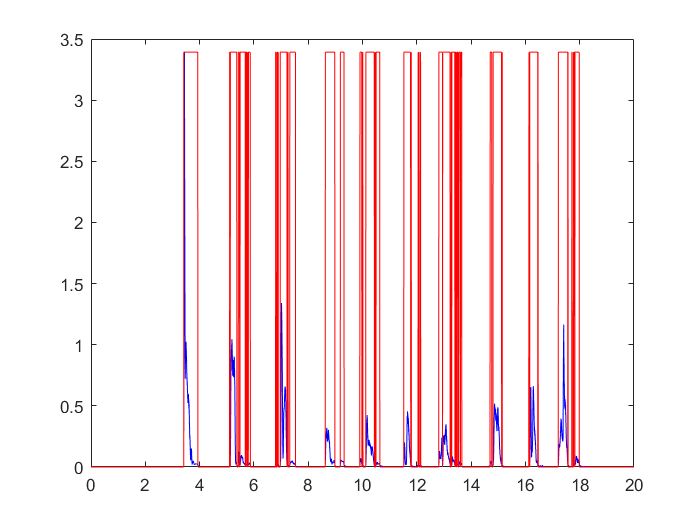

%koriscenje kratkovremenske energije, segmentacija

%prosirenje

ITU = 0.005*max(E);
ITL = 0.00001*max(E);
%ITU = 0.005*max(E); %0.005E
%ITL = 0.0001*max(E); %0.0001E

%IMX = max(E);
%IMN = max(E(2500:end));
%I1 = 0.03*(IMX-IMN) + IMN;
%I2 = 4*IMN;
%ITL = min(I1,I2)
%ITU = 5*ITL

pocetak_reci = [];
krajevi = [];

for i=2:length(E)
    if (E(i-1)<ITU)&&(E(i)>=ITU)
        pocetak_reci = [pocetak_reci i];
    end
    if (E(i-1)>ITU)&&(E(i)<=ITU)
        krajevi = [krajevi i];
    end
end

rec = zeros(length(E),1);
for i=1:length(pocetak_reci)
    rec(pocetak_reci(i):krajevi(i)) = max(E)*ones(krajevi(i)-pocetak_reci(i)+1,1);
end

figure
plot(time,E,'b', time, rec, 'r');

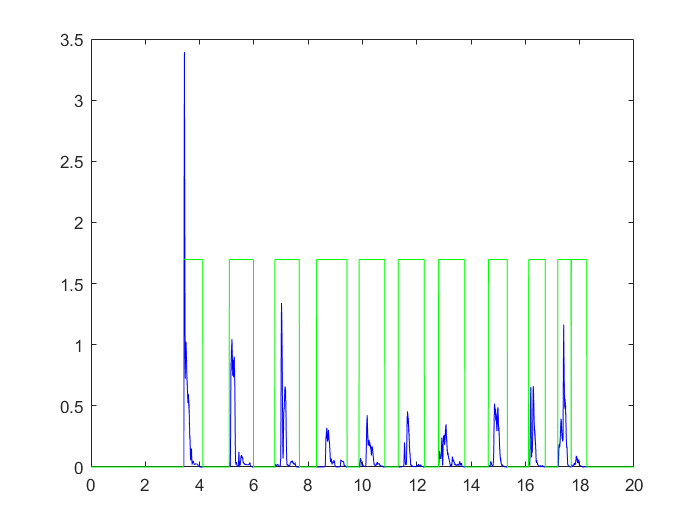

for i=1:length(pocetak_reci)
    pomeranje = pocetak_reci(i);
    while (E(pomeranje)>ITL)
        pomeranje = pomeranje-1;
    end
    pocetak_reci(i) = pomeranje;
end

for i=1:length(krajevi)
    pomeranje = krajevi(i);
    while(E(pomeranje)>ITL)
        pomeranje = pomeranje + 1;
    end
    krajevi(i) = pomeranje;
end

poc1(1) = pocetak_reci(1);
k = 1;
for i=2:length(pocetak_reci)
    if pocetak_reci(i)~=poc1(k)
        k=k+1;
        poc1(k) = pocetak_reci(i);
    end
end

kraj1(1) = krajevi(1);
k = 1;
for i=2:length(krajevi)
    if krajevi(i)~=kraj1(k)
        k=k+1;
        kraj1(k) = krajevi(i);
    end
end

pocetak = poc1;
kraj = kraj1;

rec = zeros(length(y),1);
for i=1:length(pocetak)
    rec(pocetak(i):kraj(i),1) = max(E)*ones(kraj(i)-pocetak(i)+1,1);
end

figure
plot(time, E, 'b', time, rec/2, 'g');
hold off

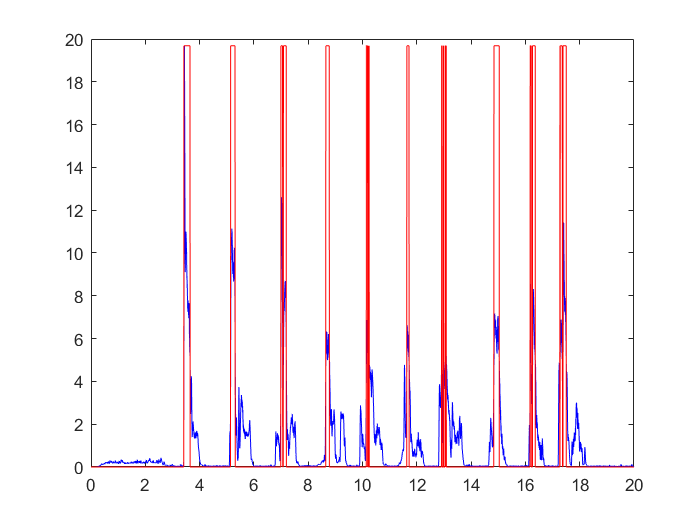

%segmentacija koriscenjem magnitude

ITU = 0.25*max(M); %0.005E
ITL = 0.002*max(M); %0.0001E

%IMX = max(E);
%IMN = max(E(2500:end));
%I1 = 0.03*(IMX-IMN) + IMN;
%I2 = 4*IMN;
%ITL = min(I1,I2)
%ITU = 5*ITL

pocetak_reci = [];
krajevi = [];

for i=2:length(M)
    if (M(i-1)<ITU)&&(M(i)>=ITU)
        pocetak_reci = [pocetak_reci i];
    end
    if (M(i-1)>ITU)&&(M(i)<=ITU)
        krajevi = [krajevi i];
    end
end

rec = zeros(length(M),1);
for i=1:length(pocetak_reci)
    rec(pocetak_reci(i):krajevi(i)) = max(M)*ones(krajevi(i)-pocetak_reci(i)+1,1);
end

figure
plot(time,M,'b', time, rec, 'r');

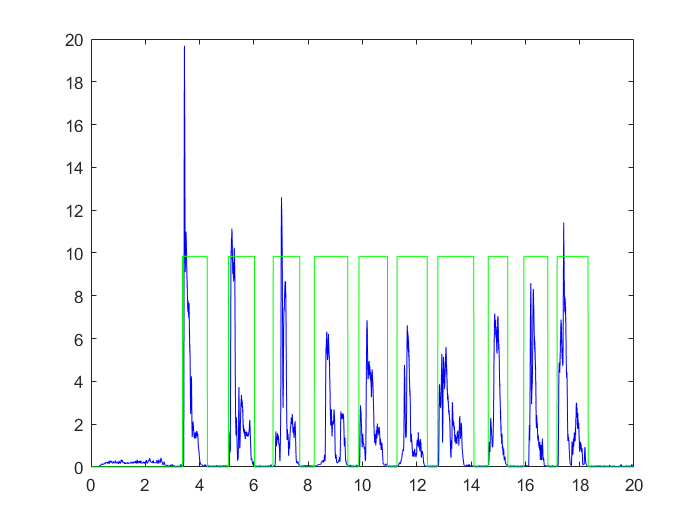


%prosirenje

for i=1:length(pocetak_reci)
    pomeranje = pocetak_reci(i);
    while (M(pomeranje)>ITL)
        pomeranje = pomeranje-1;
    end
    pocetak_reci(i) = pomeranje;
end

for i=1:length(krajevi)
    pomeranje = krajevi(i);
    while(M(pomeranje)>ITL)
        pomeranje = pomeranje + 1;
    end
    krajevi(i) = pomeranje;
end

clear poc1 kraj1
poc1(1) = pocetak_reci(1);
k = 1;
for i=2:length(pocetak_reci)
    if pocetak_reci(i)~=poc1(k)
        k=k+1;
        poc1(k) = pocetak_reci(i);
    end
end

kraj1(1) = krajevi(1);
k = 1;
for i=2:length(krajevi)
    if krajevi(i)~=kraj1(k)
        k=k+1;
        kraj1(k) = krajevi(i);
    end
end

clear rec pocetak kraj
pocetak = poc1;
kraj = kraj1;

rec = zeros(length(y),1);
for i=1:length(pocetak)
    rec(pocetak(i):kraj(i),1) = max(M)*ones(kraj(i)-pocetak(i)+1,1);
end

figure
plot(time, M, 'b', time, rec/2, 'g');
hold off

Histogrami govornog signala i tišine ne može da bude od velike pomoći s obzirom da se delovi histograma reči koje ima bezvučne plozive u sebi dosta preklapaju sa histogramom dela signala koji predstavlja tišinu. Zbog toga i jeste teško naći donju granicu za prag između tiišine i govora.

%slusanje dobijenih reci

for i=1:length(poc1)
    sound(y(pocetak(i):kraj(i)), fs);
    pause
end


#### 3.Snimiti novu sekvencu od par reči (bogatih samoglasnicima, recimo onomatopeja,...) i na osnovu tako snimljene sekvence proceniti pitch periodu sopstvenog glasa. Koristiti dve različite metode pa uporediti i komentarisati dobijene rezultate.

### ***TEORIJSKI OSVRT****:*

Pitch-perioda (osnovna učestanost glotisa) je jedan od parametara koji služe da se prepozna govornik, pošto svaka osoba ima sopstvenu pitch-periodu. Postoji više načina za procenu pitch-periode, i u ovom zadatku ćemo se osvrnuti na dva. 

#### ***PRVI METOD:***

Prvi korišćeni metod predložili su Gold i Rabiner, i prikazana je šema algoritma na slici ispod:

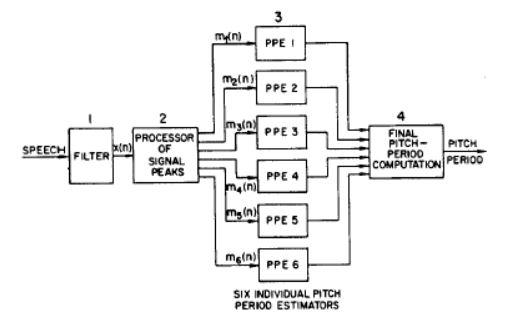

Prvi korak u algoritmu jeste filtriranje ulaznog govornog signala. Pitch-perioda se obično nalazi između 100 i 300 Hz i s obzirom na to se ulazni signal obično propušta kroz filtar propusnik opsega. Na ulaz u procesor pikova dovodi se filtrirani signal, a na izlazu se generiše šest različitih povorki impulsa $m_{i}(n)$:

$m_{1}(n)$ predstavlja povorku impulsa maksimuma govornog signala. Na mestima gde se javljaju maksimumi u govornom signalu, vrednost $m_{1}(n)$ jednaka je vrednosti tog maksimuma, inače je nula.

$m_{2}(n)$ sadrži impulse koji su jednaki razlici maksimuma i prethodnog minimuma na onom mestu na kom se pojavio maksimum.

$m_{3}(n)$ sadrži impulse koji su jednaki razlici maksimuma i prethodnog maksimuma a na mestu gde se pojavio tekući maksimum.

$m_{4}(n)$ sadrži impulse koji su jednaki negativnim vrednostima minimuma na lokacijama gde se minimum pojavio.

$m_{5}(n)
$ sadrži impulse koji su jenaki negativnoj razlici tekućeg minimuma i prethodnog maksimuma, na lokaciji gde se nalazi minimum. 

$m_{6}(n)$ sadrži impulse koji su jednaki negativnoj razlici tekućeg i prethodnog minimuma. 

U slučaju dobijanja negativne vrednosti za bilo koji od ovih signala, upisuje se vrednost nula.

Treći korak u ovom algoritmu jeste estimacija pitch-periode pomoću 6 estimatora, jer se a svaku generisanu povorku impulsa estimira posebno perioda. Ulaz u i-ti estimator je $m_{i}(n), i=1,2...,6$, a na izlazu se formira procena pitch-periode $\hat{T}_{pi},i=1,2,...,6$. Estimacija se realizuje na sledeći način: kada se pojavi prvi impuls u ulaznom signali, postavlja se tajmer na nulu i neko vreme $\tau$ (blanking time) se ne dešava ništa. Nakon isteka ovog vremena se generiše funkcija $Ae^{-\lambda t}$, gde je A konstanta jednaka intenzitetu impulsa od kojeg je brojanje krenulo. Da bi se vreme zaustavilo čeka se da impuls u dolazećoj ulaznoj sekvenci impulsa bude veći od generisane opadajuće funkcije. U tom trenutku se estimacija zaustavlja i vreme proteklo od početka brojanja smatra se pitch-periodom. Ova procedura se ponavlja pri čemu se brojač resetuje.

Parametri koje je potrebno postaviti jesu $\tau$  i $\lambda$. $\tau$ se bira tako da estimator ne može da generiše pitch-periodu manju od očekivane, a pošto najmanju pitch periodu imaju deca (oko 3.5ms), obično se za $\tau$ uzima vrednost između 3 ms i 4 ms. $\lambda$ se bira tako da ne može da se generiše pitch-perioda veća od očekivane (to su neki duboki muški glasovi kod kojih je pitch perioda oko 10ms), te se za ovaj parametar usvaja od 120 do 150 $s^{-1}$, odnosno 1/$\lambda$  je između 6ms i 8ms. 

Poslednji korak u algoritmu predstavlja konačnu odluku u proceni pitch-periode, na osnovu prethodnih 6 dobijenih estimacija, kao i procene iz prethodnog trenutka. U ovom zadatku konačna procena vršena je kao medijana ulaznih procena. 

#### *REZULTATI:*

Prilikom estimacije pitch periode, u govornom signalu koji je snimljen prvo je potrebno radzvojiti delove koji predstavljaju govor od onih koji su tišina, iz razloga što nam je za estimaciju pitch periode od značaja samo deo signala koji nije tišina.

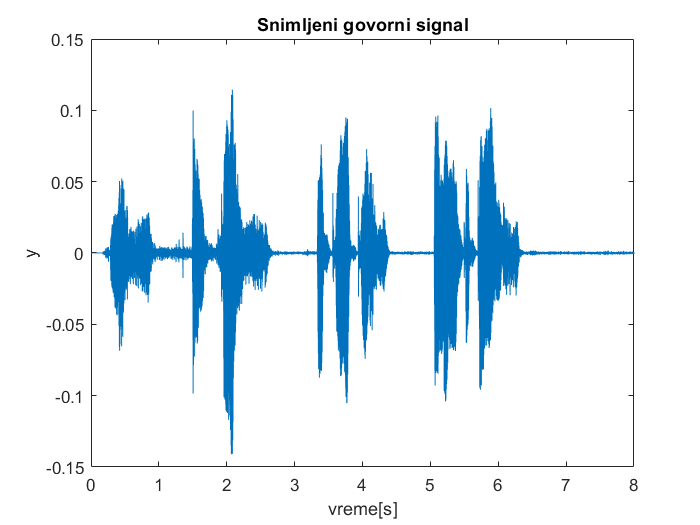


clear all;
close all;
clc;

fs=8000;% frekvencija odabiranja
trajanje_sek=8; % trajanje snimanja
N=trajanje_sek*fs; % broj odbiraka snimljenog signala
T=1/fs; % perioda odabiranja

[y, fs]=audioread('recisasamoglasnicima.wav');
%%
figure(1)
plot(T:T:length(y)*T,y)
title('Snimljeni govorni signal')
xlabel('vreme[s]')
ylabel('y')

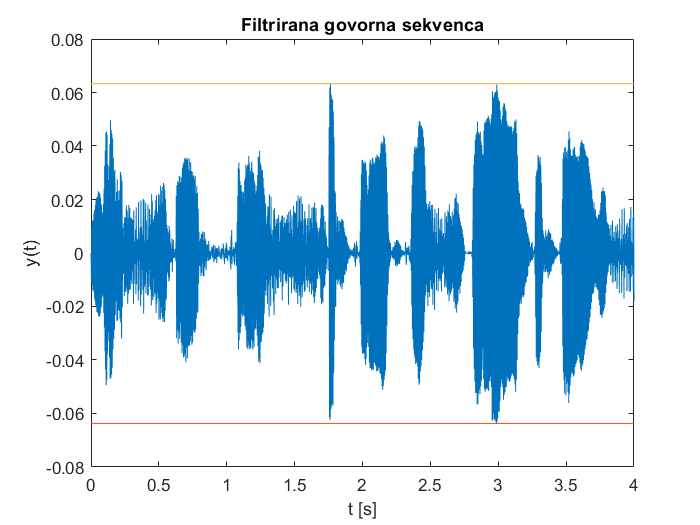

win = round(fs*15e-3);
NN = floor(N/(win/2));
lambda = 120/fs;
tau = round(fs*4e-3);
poceci = [2500 12000 27000 40000];
krajevi = [7500 21000 35000 50000];
estim = [];
yc=[];
yc=[yc, y(poceci(1):krajevi(1))'];
yc=[yc, y(poceci(2):krajevi(2))'];
yc=[yc, y(poceci(3):krajevi(3))'];
yc=[yc, y(poceci(4):krajevi(4))'];

time = 0:1/fs:(length(yc)-1)/fs;

y = yc;

% filtriranje
[B,A] = butter(6, 300/(fs/2));
yf = filter(B, A, y);
y = yf;
N = length(y);
figure
plot(time, y); hold on;
title('Filtrirana govorna sekvenca'); xlabel('t [s]'); ylabel('y(t)');
xlim([0, length(time)/fs]);
plot([0, length(time)/fs], [min(y), min(y)], [0, length(time)/fs], [max(y), max(y)]);

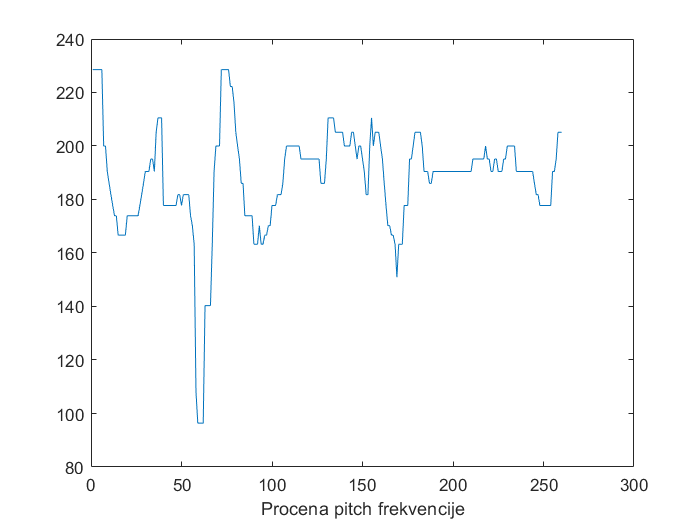


%% Formirati povorke impulsa iz snimljenog signala
% detekcija lokalnih maks i min u signalu
% inicijalizacija potrebnih vektora
N = length(y);
maxs = zeros(1, N);
mins = zeros(1, N);
maxidx = []; % pozicije maks i min
minidx = [];

% 6 povorki impulsa
m1 = zeros(1, N);
m2 = zeros(1,N);
m3 = zeros(1,N);
m4 = zeros(1,N);
m5 = zeros(1,N);
m6 = zeros(1,N);

% Formiranje m1 i m4
for i = 2:N-1 % zbog poredjenja sa prethodnom i narednom vrednoscu
    if y(i) > y(i-1) && y(i) > y(i+1) % lokalni maks
        maxs(i) = y(i);
        maxidx = [maxidx i];
        m1(i) = max(0, y(i));
    end
    if y(i) < y(i-1) && y(i) < y(i+1)
        mins(i) = y(i);
        minidx = [minidx i];
        m4(i) = max(0, -y(i));
    end
end

% Formiranje m2 i m3, na poziciji tekucih maksimuma
maxp = 0;  % prethodni maks za tekuci maks, prvi!, kasnije se uvek azurira
for i = maxidx
    if isempty(find(minidx < i, 1, 'last')) % moze da se desi da kad posmatramo bilo koji tekuci maks da se prethodni (tekuci) min nije pojavio, posto posmatramo govorni signal koji je periodican, uvek ce se pojavljivati maks, pa min, ali da bi se zastitili, posmatracemo da li pre maks postoji neki min
        minp = 0;  % ako se nije pojavio min pre tekuceg maks, stavicemo min na 0
    else
        idx = find(minidx < i, 1, 'last');
        minp = mins(minidx(idx));
    end
    m2(i) = max(0, maxs(i) - minp);
    m3(i) = max(0, maxs(i) - maxp);
    maxp = maxs(i);
end

% Formiranje m5 i m6
minp = 0;
for i = minidx
    if isempty(find(maxidx < i, 1, 'last'))
        maxp = 0;
    else
        idx = find(maxidx < i, 1, 'last');
        maxp = maxs(maxidx(idx));
    end
    m5(i) = max(0, -(mins(i) - maxp));
    m6(i) = max(0, -(mins(i) - minp));
    minp = mins(i);
end

n = 1:10000;
%figure; plot(time(n), y(n)); title('Samoglasnik A'); xlabel('t(s)');
%figure; stem(time(n), m1(n)); title('m1(t)'); xlabel('t(s)');
%figure; stem(time(n), m2(n)); title('m2(t)'); xlabel('t(s)');
%figure; stem(time(n), m3(n)); title('m3(t)'); xlabel('t(s)');
%figure; stem(time(n), m4(n)); title('m4(t)'); xlabel('t(s)');
%figure; stem(time(n), m5(n)); title('m5(t)'); xlabel('t(s)');
%figure; stem(time(n), m6(n)); title('m6(t)'); xlabel('t(s)');

%% funkcija estimator(x, lambda, tau, win, fs) koja ce na osnovu datih sekvenci impulsa proceniti pitch frekvenciju

% Procena periode
win = round(fs*30e-3);
NN = floor(N/(win/2));
lambda = 120/fs;
tau = round(fs*4e-3);
% tau=3;
pt1 = zeros(1, NN); pt2 = zeros(1, NN); pt3 = zeros(1, NN);
pt4 = zeros(1, NN); pt5 = zeros(1, NN); pt6 = zeros(1, NN);
pt = zeros(1, NN);
k = 2;
for k_win = 1:win/2:N-win+1
    % prvi estimator
    x = m1(k_win:k_win+win-1);
    pt1(k) = Estimator(x, lambda, tau, win, fs);
    % drugi estimator
    x = m2(k_win:k_win+win-1);
    pt2(k) = Estimator(x, lambda, tau, win, fs);
    % treci estimator
    x = m3(k_win:k_win+win-1);
    pt3(k) = Estimator(x, lambda, tau, win, fs);
    % cetvrti estimator
    x = m4(k_win:k_win+win-1);
    pt4(k) = Estimator(x, lambda, tau, win, fs);
    % peti estimator
    x = m5(k_win:k_win+win-1);
    pt5(k) = Estimator(x, lambda, tau, win, fs);
    % sesti estimator
    x = m6(k_win:k_win+win-1);
    pt6(k) = Estimator(x, lambda, tau, win, fs);
    
    pt(k) = nanmedian([pt1(k) pt2(k) pt3(k) pt4(k) pt5(k) pt6(k) pt(k-1)]);
    k = k + 1;
end


% Konacna procena
pitchT = [];
for l = 4:length(pt)-3
    pitchT = [pitchT median(pt(l-3:l+3))];
end
figure
plot(1./pitchT*fs); xlabel('Procena pitch frekvencije');

#### ***DRUGI METOD:***

Druga metoda korišćena u ovom zadatku jeste metoda zasnovana na proceni autokorelacione funkcije. Autokorelaciona funkcija se računa preko formule


$$R_{x}(k) = E\{x(n)x(n+k)\}$$


a usled nepoznavanja gustine verovatnoće odbiraka procesa, može se estimirati kao


$$\hat{R}_{x}(k) = \lim_{N->\infty } \frac{1}{2N+1}\sum_{n=-N}^{N}x(n)x(n+k)$$


odnosno u realnim procenama:


$$\[ \hat{R}_{x}(k) = \frac{1}{2N+1}\sum_{n=-N}^{N}x(n)x(n+k) \]$$


Ako je signal x(n) periodičan sa periodom ponavljanja P, autokorelaciona fja bi morala biti periodična sa istom periodom P, a na grafiku Rx će biti izražen pik na vrednosti P. Pošto kod govornog signala postoje različite prostoperiodične komponente, u Rx će biti više izraženih pikova.

U postupku procene Rx koriste se prozorske funkcije koje imaju za cilj da procene ovu funkciju samo na jednom određenom segmentu signala. Tada se za Rx koristi sledeća formula:


$$\hat{R}_x^m(k) = \frac{1}{2N+1}\sum_{n=-N}^{N}x(n)w(m-n)x(n+k)w(m-n-k)$$


Iako su uočljivi pikovi u Rx, nije jasno koji od tih pikova potiče od osnovnog formanta. Zbog toga se često koriste tehnike klipovanja. One podrazumevaju da se na odbirke akustičnog talasa primene određene nelinearne funkcije. Za parametar Cl se obično preporučuje oko 30 (izmedju 30 i 60) procenata od maksimalne vrednosti signala. Rx nakon klipovanja ima mnogo izraženiji pik. 

#### ***REZULTATI:***

clear all;
close all;
clc;

%% Snimanje sekvence

% x=audiorecorder(fs,16,1);
% disp('Snimanje pocinje')
% recordblocking(x,trajanje)
% disp('Snimanje zavrseno')
% Snimljena je govorna sekvenca u trajanju od 6s koja sadrzi 6 reci
% onomatopeja, psihologija i samoglasnik

%% Reprodukcija zvuka

% y=getaudiodata(x);
% sound(y,fs);
% audiowrite('sekvenca_E.wav',y,fs);
[y, fs]=audioread('recisasamoglasnicima.wav');
poceci = [2500 12000 27000 40000];
krajevi = [7500 21000 35000 50000];
poc = poceci(1);
kraj = krajevi(1);
estim = [];
yc=[];
yc=[yc, y(poceci(1):krajevi(1))'];
yc=[yc, y(poceci(2):krajevi(2))'];
yc=[yc, y(poceci(3):krajevi(3))'];
yc=[yc, y(poceci(4):krajevi(4))'];
%trajanje_sek = 8;
%N = fs*trajanje_sek;
N = kraj-poc+1;
T =1/fs;
% figure(1)
% plot(T:T:length(y)*T,y)
% title('Snimljeni govorni signal')
% xlabel('vreme[s]')
% ylabel('y')

%% Filtriranje

[B, A]=butter(6, [100 900]/(fs/2));
y_f=filter(B,A,yc);

% Procena pitch periode pomocu autokorelacione funkcije

%Rxx=AKF(y_f); % autokorelaciona funkcija bez klipovanja

% figure
% t=T:T:length(y_f)*T;
% plot(t*fs, Rxx);
% axis([0 500 -0.001 0.001 ])
% title('Autokorelaciona funkcija pre klipovanja')
% xlabel('n (broj odbiraka)')
% ylabel('R_{xx}[n]')


%% Centralno klipovanje

cl = 0.01*max(y_f);
N = length(yc);
y_klip=zeros(1,N);
for i=1:N
    if (y_f(i)<cl && y_f(i)>-cl)
        y_klip(i)=0;
    else
        if(y_f(i)>cl)
            y_klip(i)=y_f(i)-cl;
        else
            y_klip(i)=y_f(i)+cl;
        end
        %y_3nk(i) = y_f(i);
    end
end


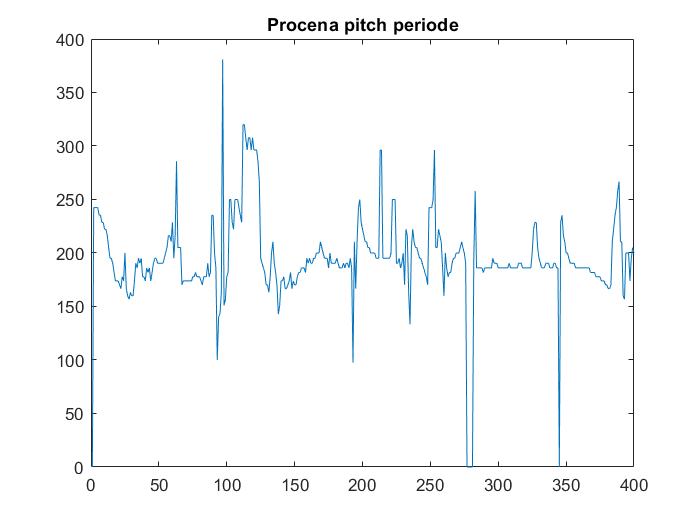

N = length(y_klip);
win = round(fs*20e-3);
NN = floor(N/(win/2));
pt = zeros(1, NN);
k = 1;

for k_win = 1:win/2:N-win+1
    x = y_klip(k_win:k_win+win-1);
    akf = AKF(x);
    k = k + 1;
    [pics,locs] = findpeaks(akf);
    loc = locs(pics>0);
    loc = loc(loc>20);
    if (isempty(loc))
        pt(k) = 0;
    else
        pt(k) = loc(1);
    end
    
end
pp = zeros(1,length(pt));
for i = 1:length(pt)
    if (pt(i) ~= 0)
        pp(i) = 1./pt(i)*fs;
    else
        pp(i) = 0;
    end
end
figure()
plot(pp);
title('Procena pitch periode');

Konačne procene obeju metoda daju vrednost pitch periode 190Hz i vrednosti su veoma slične. U ovom slučaju je dobijeno tako, mada inače metoda procene preko autokorelacione funkcije važi za sigurniju i metodu koja vrši bolju procenu.

## Drugi zadatak:

#### 1. Korišćenjem komercijalnog mikrofona u programskom okruženju MATLAB, snimiti govornu sekvencu u dužini od 20-ak sekundi. Sekvencu snimiti sa frekvencijom odabiranja 8 kHz u šesnaestobitnoj (default) rezoluciji.

#### 2. Isprojektovati 𝜇 = 100 i 𝜇 = 500 kompanding kvantizator sa 4, 8 i 12 bita i za njih odrediti zavisnost odnosa signal-šum za različite vrednosti odnosa (xmax / sigma ). Ovaj odnos menjati promenom varijanse korisnog signala, prostim skaliranjem početne snimljene sekvence. Prikazati rezultate grafički.

### ***TEORIJSKI OSVRT:***

U digitalizaciji govornog signala od značaja su kvantizacija po vremenu (odabiranje), i po amplitudi (kvantizatori o kojima će ovde biti reči). Zadatak kvantizatora jeste da ulazni diskretni signal x(n) koji može uzeti bilo koju vrednost od -Xmax do Xmax, preslika u neki signal x1(n) koji uzima vrednosti iz diskretnog skupa sa konačnim brojem elemenata. Ovo omogućava kodiranje signala koji se dalje šalje u komunikacioni kanal. Ono o čemu je potrebno voditi računa i u ovom delu digitalizacije govornog isgnala jeste da gubitak informacija koji  nastaje kvantizacijom bude minimalan. 

Kompanding kvantizator se realizuje korišćenjem funkcije


$$F(x[n]) = x_{max}\frac{log \left[1+\mu \frac{|x[n]|}{x_{max} }\right]}{log[1+\mu ]}\cdot sign(x[n])$$


Za rekonstrukciju ulaznog signala x dovoljno je primeniti inverznu funkciju od F(x).

Odnos signal/šum ima oblik:


$$SNR[dB] = 6B + 4.77 - 20log_{10}(ln(1+\mu ))-10log_{10}\left[ 1+\left( \frac{x_{max}}{\mu \sigma_{x}}\right)^2 + \sqrt{2}\left(\frac{x_{max}}{\mu \sigma_{x}}\right) \right]$$


Opadanje odnosa signal/šum sa povećanjem xmax/sigma je umanjeno mi puta, i ovo je izraženije za veće mi.

Kod ovog kvantizatora više značaja se daje malim vrednostima (zbog čega se i koristi logaritamska funckija). Prednost mi kompandinga u odnosu na obični kompanding je u tome što mi kompanding izbegava problem koji običan kompanding ima u nulizbog korišćenja logaritamske funkcije koja u nuli nije definisana.

### ***REZULTATI:***

clear
close all
clc
fs = 8000;
T = 1/fs;
trajanje = 20; %8 sekundi za prvi pod 3
N = trajanje*fs;
nbits = 16;
nchans = 1;

% snimanje sekvence

x = audiorecorder(fs,nbits,nchans);
disp('Start.')

Start.


recordblocking(x, trajanje);
disp('Stop.')

Stop.


%pustanje snimljene sekvence

%play(x)
y = getaudiodata(x);
sound(y, fs); %podraz. fs = 8192
%potrebno je da vrednosti y budu u intervalu (-1,1)


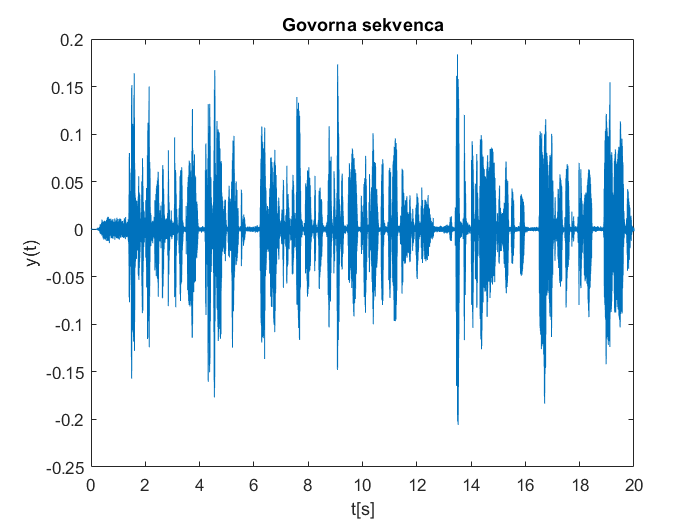

%audiowrite('sekvenca_drugi.wav', y, fs);
[y,fs] = audioread('sekvenca_drugi.wav');

figure
plot(0:1/fs:(length(y)-1)/fs, y);
title('Govorna sekvenca'); xlabel('t[s]'); ylabel('y(t)');

    "Broj bitova:"    "4"



SNR_100 = 14.964795


SNR_500 = 12.652670


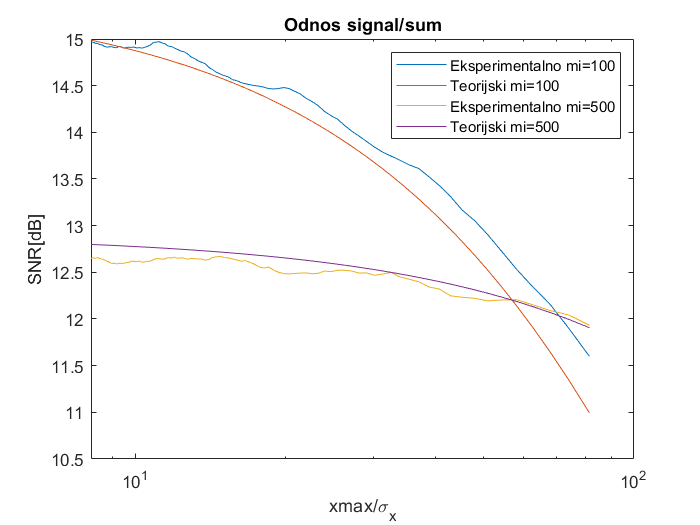

    "Broj bitova:"    "8"



SNR_100 = 39.221496


SNR_500 = 36.959028


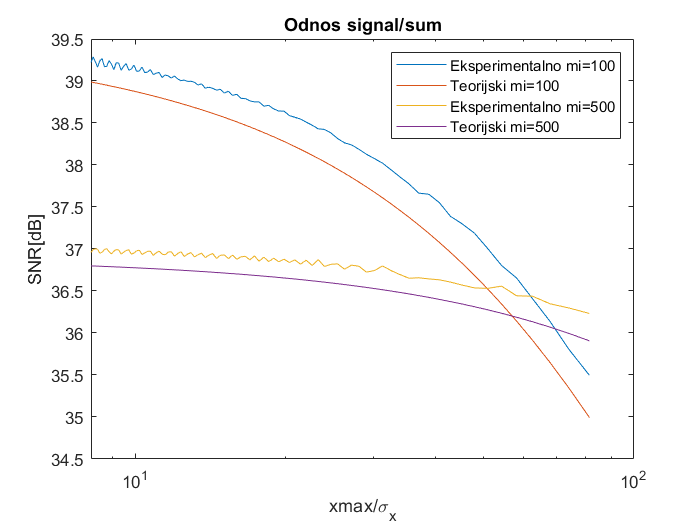

    "Broj bitova:"    "12"



SNR_100 = 63.330711


SNR_500 = 61.054354


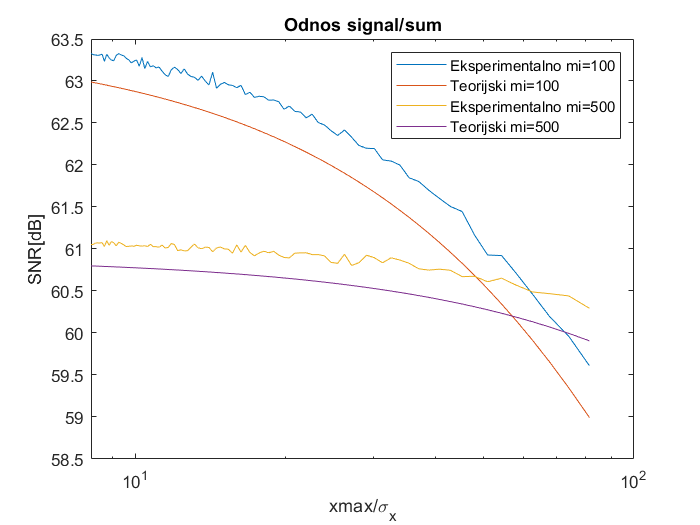


[x,Fs]=audioread('sekvenca_drugi.wav');
Xmax = max(abs(x));
N = length(x);
b = 8;
M = 2^b;

d = 2*Xmax/(2^b);
Xmax = max(abs(x));
br_bit = [4,8,12];

for b = br_bit
    disp(["Broj bitova:",b])
    figure
    for mi=[100,500]
        aten = 0.1:0.01:1; %utisavanje
        M = 2^b; %broj kvantizacionih nivoa
        d = 2*Xmax/M; %korak kvantizacije
        SNR1 = [];
        xvar1 = [];
        for i=1:length(aten)
            x1 = aten(i)*x;
            xvar1 = [xvar1 var(x1)];
            x_comp = Xmax*log10(1+mi*abs(x1)/Xmax)/(log10(1+mi)).*(sign(x1));
            xq_mi = round(x_comp/d)*d; %kvantizovan signal
            %xq_mi
            x_mi_decomp =1/mi*sign(xq_mi).*((1+mi).^(abs(xq_mi)/Xmax)-1)*Xmax;
            SNR1 = [SNR1 10*log10(var(x1)/var(x1-x_mi_decomp))];
        end
        %figure
        %plot(1:N,x_mi_decomp,'b');
        %hold on;
        %plot(1:N,x,'r--');
        %title("Govorni signal")
        %hold off
        %figure
        semilogx(Xmax./(sqrt(xvar1)),SNR1);
        %plot(Xmax./(sqrt(xvar)),SNR,'b');
        hold on;
        %semilogx(Xmax./(sqrt(xvar)),4.77+6*b-20*log10(Xmax./sqrt(xvar)),'r--');
        semilogx(Xmax./(sqrt(xvar1)),4.77+6*b-20*log10(log(1+mi))-10*log10(1+(Xmax./mi)^2./xvar1+sqrt(2)*Xmax./mi./sqrt(xvar1)));
        legend('Eksperimentalno','Teorijski')
        fprintf('SNR_%d = %f\n',mi, 10*log10(var(x)/var(x-x_mi_decomp)));
    end
    title("Odnos signal/sum")
    xlabel("xmax/\sigma_{x}")
    ylabel("SNR[dB]")
    legend('Eksperimentalno mi=100','Teorijski mi=100','Eksperimentalno mi=500','Teorijski mi=500')
    hold off
end

Na graficima je prikazano kako odnos signal/šum zavisi od vrednosti odnosa $x_{max}/\sigma_x$, gde je ovaj odnos menjan skaliranjem ulazne sekvence.

Bolja karakteristika se dobija za veću vrednost $\mu
$ jer je opseg pre nego što karakteristika počne da pada širi. Takođe, sa porastom broja bita kvantizacije SNR je veće.

#### 3. Isprojektovati Delta kvantizator za sekvencu iz tačke 1. Adekvatno podesiti parametar Δ tako da se dobije što bolji kvalitet kvantizacije. Uporediti oblike originalnog i kvantizovanog signala. Šta se dešava kada je korak kvantizacije Δ previše mali ili previše veliki? Da li se histogram priraštaja može koristiti za određivanje adekvatnog parametra Δ? Pratiti kvalitet zvuka i promene u amplitudi za svaki slučaj

### ***TEORIJSKI OSVRT:***

Delta kvantizator je oblik diferencijalnog kvantizatora, koji polazi od pretpostavke da je preioda odabiranja mnogo manja od Nikvistove periode, zbog čega se pretpostavlja da su sve promene u signalu male i informaciju nosi samo znak promene. Za ovakvu kvantizaciju koristi se 1 bit koji ima vrednost 0 ako je promena pozitivna i 1 ako je promena negativna. Glavna prednost delta kvantizacije je to što je realizacija jednsotavna.

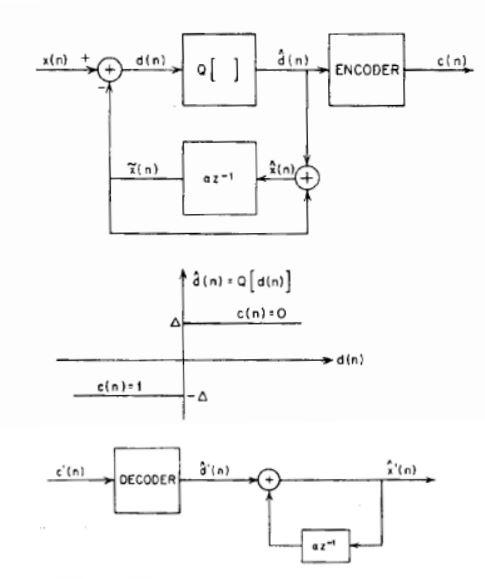

Važi diferencijalna jednačina $\hat{x}[n] = \alpha \hat{x}[n-1] + \hat d [n]$. Za $\alpha = 1$ dobija se akumulator sa inkrementom $\pm \Delta$. Uslov da kvantizovani signal može da isprati brzinu promene originalnog signala je  $\frac{\Delta}{T} \geq max|x^{'}[n]|$, gde je $x^{'}[n]$ izvod signala x[n]. Ako ovo nije ispunjeno dolazi do distorzije signala usled prekoračenja strmine i rekonstruisani signal će kasniti za originalnim. Sa druge strane, ako se usvoji previše veliko $\Delta$, moglo bi da dođe do pojave oscilacija na izlaznom signalu u delu gde je originalni signal miran. Ovaj kvantizator se još naziva i linearni delta kvantizator jer na segmentima gde dolazi do kašnjenja za originalnim signalom, to kašnjenje je sa konstantnim nagibom. Mana ovog kvantizatora je u tome što često mora da se podešava parametar $\Delta$, a čak za isti signal može da važi da za različite delove signala odgovaraju različite vrednosti $\Delta$ kako bi kvantizator davao zadovoljavajuće rezultate. Ovo se može prevazići uvođenjem adaptivnog delta kvantizatora.

### ***REZULTATI:***

Potrebno je podesiti parametar delta da kvalitet dobijenog rekonstruisanog signala bude što bolji. Za to je posmatran određeni opseg za parametar delta, i kao mera kvaliteta kvantizatora posmatran je odnos signal/šum. Kao adekvatan delta parametar uzeta je ona vrednost za koju je odnos signal/šum rekonstruisanog signala najbolja, što je u ovom slučaju 0,014.

clear

[x,Fs]=audioread('sekvenca_drugi.wav');
%x = x(10000:15000);
L = length(x);
t = 0:1/Fs:(length(x)-1)/Fs;
%x = round(x*255);


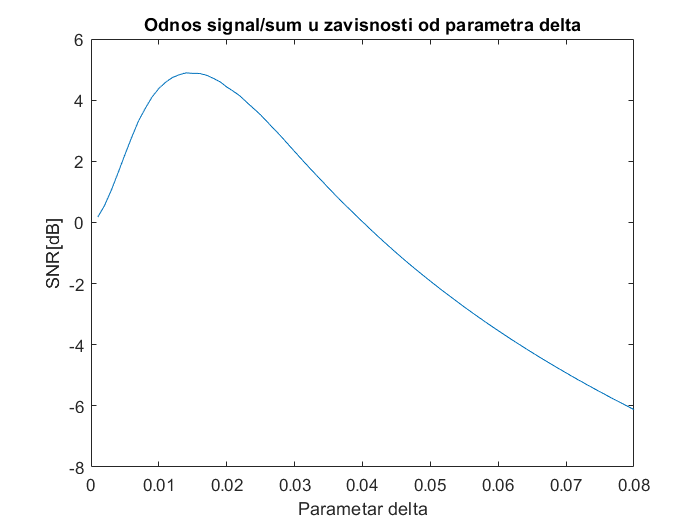

k1=0;
arr=0.001:0.001:0.08;
for Q=arr
    xmean = mean(x);
    d = zeros(1,L);
    d(1) = x(1);
    c = zeros(1,L);
    dd = zeros(1,L);
    dd(1) = Q;
    xx = zeros(1,L);
    e = zeros(1,L);
    xx(1) = xmean + dd(1);
    
    %delta modulacija
    for i=2:L
        d(i) = x(i)-xx(i-1);
        if d(i)>0
            c(i) = 0;
            dd(i) = Q;
        else
            c(i) = 1;
            dd(i) = -Q;
        end
        xx(i) = xx(i-1) + dd(i);
        e(i) = x(i)-xx(i);
    end
    k1=k1+1;
    SNR(k1) = 10*log10(var(x)/var(e));
    
end
figure
plot(arr,SNR)
title("Odnos signal/sum u zavisnosti od parametra delta")
xlabel("Parametar delta")
ylabel("SNR[dB]")


[~,ind] = max(SNR);
Q = arr(ind);


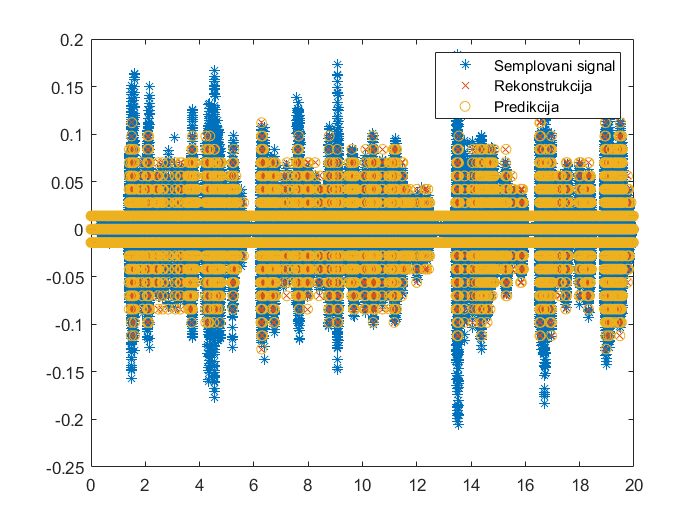


xmean = mean(x);

%pocetni uslovi
d = zeros(1,L);
d(1) = x(1);
c = zeros(1,L);
dd = zeros(1,L);
dd(1) = Q;
xx = zeros(1,L);
xx(1) = xmean + dd(1);

%delta modulacija
for i=2:L
    d(i) = x(i)-xx(i-1);
    if d(i)>0
        c(i) = 0;
        dd(i) = Q;
    else
        c(i) = 1;
        dd(i) = -Q;
    end
    xx(i) = xx(i-1) + dd(i);
end

figure
plot(t,x,'*',t,xx,'x',t(2:L),xx(1:(L-1)),'o');
legend('Semplovani signal', 'Rekonstrukcija','Predikcija');

sound(xx,Fs);

Preslušavanjem dobijenog zvučnog signala uočeno je da je govorni deo zadržan i reči u govornoj sekvenci mogu da se prepoznaju. Primećeno je prisustvo granularnog šuma što se vidi i sa grafika dobijenog signala i preslušavanjem, a koji je očekivan kao posledica parametra delta. Povećanjem parametra delta dolazi do gubljenja informacija i sve što bi se čulo na signalu na izlazu iz kvantizatora je glasno krčanje. 

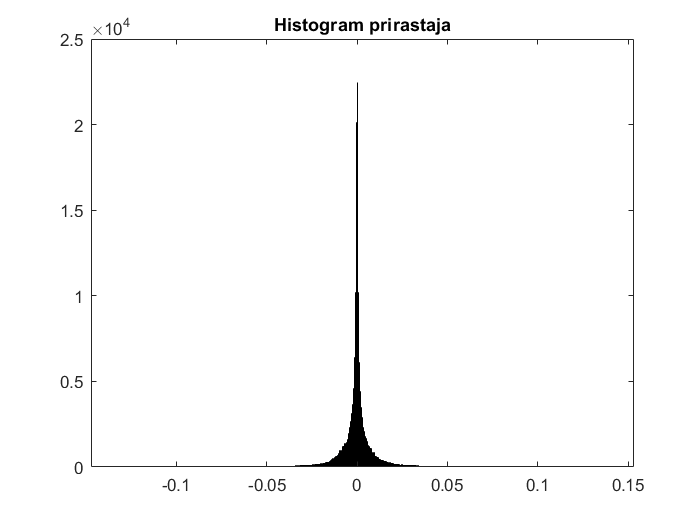

%histogram priraštaja
figure
histogram(diff(x))
title("Histogram prirastaja")

Sa histograma ne moze da se vidi mnogo toga iz razloga sto je u pitanju laplasova raspodela.

## SKRIVENI MARKOVLJEV MODEL

### Tekst zadatka:

#### 1. Pretpostaviti eksperiment u kome se, u skladu sa matricom tranzicije 𝐴, na slučajan način bira jedna od tri urne i na slučajan način iz nje izvlači kuglica. Pretpostaviti dalje da u prvoj urni ima 5 belih, 2 crne i 1 zelena kuglica, u drugoj 2 bele, 7 crnih i 4 zelene, dok u trećoj urni ima 1 bela, 3 crne i 6 zelenih. Na osnovu ovakvih pretpostavki definisati Skriveni Markovljev model.

#### 2. Usvojiti 𝑎 = 0.05 i 𝑏 = 0.1 pa generisati sekvencu od 100 opservacija. Za tako generisanu sekvencu opservacija rešiti prvi i drugi problem Markovljevih modela. Proceniti verovatnoću tačne rekonstrukcije stanja u sekvenci (uspešnost rešenja drugog modela)

#### 3. Ponoviti prethodnu tačku sa 𝑎 = 0.2 i 𝑏 = 0.33. Komentarisati dobijene rezultate, odnosno na koji način promena ovih parametara utiče na efikasnost rešavanja drugog problema.

### ***TEORIJSKI OSVRT:***

Skriveni Markovljevi modeli se koriste za opisivanjesistema kada nemamo informaciju o tome u kom se stanju sistem nalazi. 

Elementi skrivenih Markovljevih modela:

1.N-broj stanja u modelu

2.A-matrica verovatnoća tranzicija iz jednog stanja u drugo

3.B-matrica opservacija za slučaj diskretnog alfabeta ili funkcija gustine verovatnoće opservacija za neprekidan alfabet

4.M-broj mogućih opservacija

5.$\Pi$-verovatnoće početnih stanja

Postoje tri problema koja se rešavaju:

1-Određivanje verovatnoće opservacija ako je poznat model i opservacije

2-Rekonstrukcija stanja kroz koje sistem prolazi ako je poznat model i opservacije

3-Generisanje modela $\lambda (A,B,\Pi )$ ako su poznate opservacije.

REZULTATI:

Prvi problem rešavan je preko forward-backward algoritma, koji se sastoji iz tri koraka: inicijalizacije, indukcije i terimnacije.

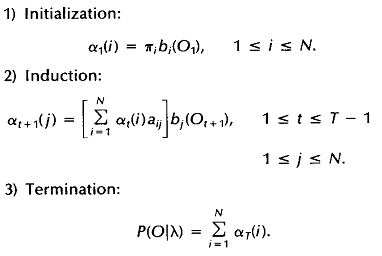

Drugi problem Markovljevih modela rešavan je Viterbijevim algoritmom dinamičkog programiranja. Kod ovog algoritma je definisan princpit optimalnosti koji kaže da je svaki deo optimalne trajektorije optimalna trajektorija. Sastoji se o nekoliko koraka: inicijalizacije, rekurzije, terminacije, i poslendjeg koraka.

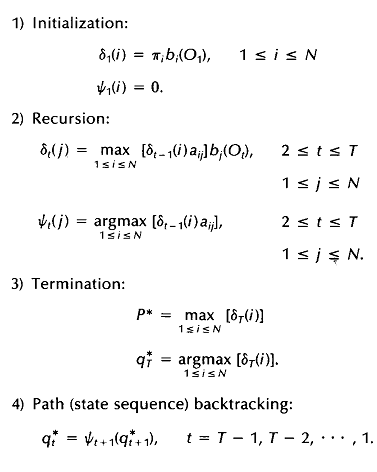

clear all
close all
clc

N=3; % broj stanja (urni)
M=3; % broj razlicitih boja
T=100; % broj opservacija

a=0.05;
b=0.1;
%a=0.2;
%b=0.33;

% Matrica tranzicije
A=[1-3*a a 2*a; b 1-2*b b; 0.1 0.1 0.8];
% Matrica opservacija
B=[5/8 2/8 1/8; 2/13 7/13 4/13; 1/10 3/10 6/10];
% Matrica inicijalnih verovatnoca
Pi=[1/3 1/3 1/3];

Q=zeros(1,T); % skup stanja u kojima se nalazimo u svakom  od t(100) trenutaka
O=zeros(1,T); % skup opservacija
Q(1)=Generator(Pi);

for t=1:T-1
    O(t)=Generator(B(Q(t),:));
    Q(t+1)=Generator(A(Q(t),:));
end
O(T)=Generator(B(Q(T),:));



% Problem 1

alfa=zeros(T,N); % forward koeficijenti-alfa(t, i) je varovatnoca da je u trenutku t aktivno stanje Si

% Inicijalizacija

for i=1:N
    alfa(1,i)=Pi(i)*B(i, O(1));
end

% Indukcija

for t=1:T-1
    for j=1:N
        for i=1:N
            alfa(t+1, i)=alfa(t+1, i)+alfa(t,j)*A(j,i)*B(i, O(t+1));
        end
    end
end

% Terminacija

P1=0;
P1=sum(alfa(T,:));


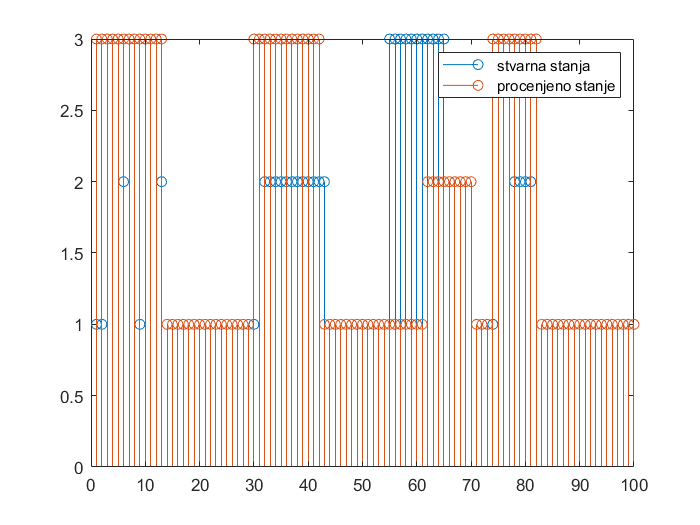

%Problem 2


% clc
% clear all
% close all


[v,P1] = myViterbi(O,Pi,A,B);

tacnost_drugog_modela = sum(v==Q);
figure
stem(Q)
hold on
stem(v)
legend("stvarna stanja", "procenjeno stanje")


verovatnoca_rekonstrukcija = Pi(v(1));
for i = 1:(length(v)-1)
    verovatnoca_rekonstrukcija= verovatnoca_rekonstrukcija * A(v(i),v(i+1));
end

U ovom slučaju dobijena verovatnoća je 4,5739e-48, a tačnost drugog problema je 68%. Verovatnoća tačne rekonstrukcije je 4,7340e-16.

clear all
close all
clc

N=3; % broj stanja (urni)
M=3; % broj razlicitih boja
T=100; % broj opservacija

%a=0.05;
%b=0.1;
a=0.2;
b=0.33;

% Matrica tranzicije
A=[1-3*a a 2*a; b 1-2*b b; 0.1 0.1 0.8];
% Matrica opservacija
B=[5/8 2/8 1/8; 2/13 7/13 4/13; 1/10 3/10 6/10];
% Matrica inicijalnih verovatnoca
Pi=[1/3 1/3 1/3];

Q=zeros(1,T); % skup stanja u kojima se nalazimo u svakom  od t(100) trenutaka
O=zeros(1,T); % skup opservacija
Q(1)=Generator(Pi);

for t=1:T-1
    O(t)=Generator(B(Q(t),:));
    Q(t+1)=Generator(A(Q(t),:));
end
O(T)=Generator(B(Q(T),:));



% Problem 1

alfa=zeros(T,N); % forward koeficijenti-alfa(t, i) je varovatnoca da je u trenutku t aktivno stanje Si

% Inicijalizacija

for i=1:N
    alfa(1,i)=Pi(i)*B(i, O(1));
end

% Indukcija

for t=1:T-1
    for j=1:N
        for i=1:N
            alfa(t+1, i)=alfa(t+1, i)+alfa(t,j)*A(j,i)*B(i, O(t+1));
        end
    end
end

% Terminacija

P1=0;
P1=sum(alfa(T,:));


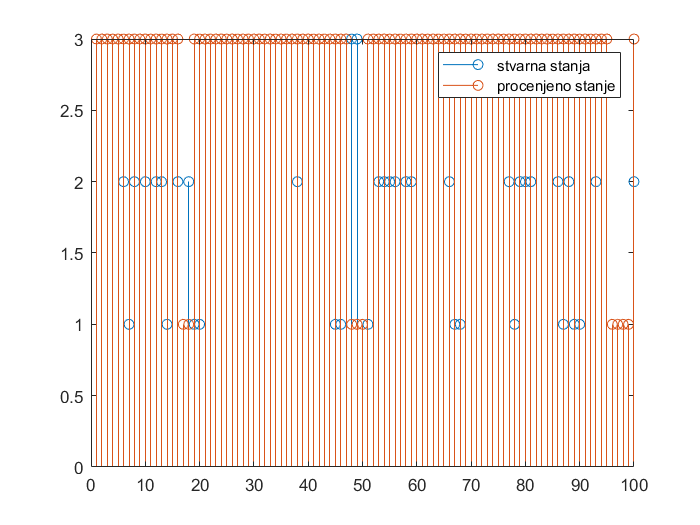

%Problem 2


% clc
% clear all
% close all


[v,P1] = myViterbi(O,Pi,A,B);

tacnost_drugog_modela = sum(v==Q);
figure
stem(Q)
hold on
stem(v)
legend("stvarna stanja", "procenjeno stanje")


verovatnoca_rekonstrukcija = Pi(v(1));
for i = 1:(length(v)-1)
    verovatnoca_rekonstrukcija= verovatnoca_rekonstrukcija * A(v(i),v(i+1));
end

Dobijena verovatnoća je 3,9283e-44, a tačnost drugog problema je 76%. Verovatnoća rekonstrukcije je 3,2378e-16.

Ovi rezultati su dobijeni na osnovu jednog eksperimenta, tako da je vrlo moguće da nisu dovoljno ilustrativni. Ponovnim pokretanjem koda dobijaju se drugačiji rezultati. Ipak, određena pravila se uočavaju. Ako su verovatnoće prelaska iz jednog u bilo koje drugo stanje slične, rezultati rešenja prvog i drugog Markovljevog modela će više varirati, dok ako sistem ima verovatnoću da ako dodje u neko stanje u njemu i ostane, rezultati koji se dobijaju biće sličniji. U oba slučaja verovatnoće su male.